# **Matlab案例代码解析**

## 2. 典型绘图案例

### 2.7 知乎提问

#### 2.7.1 如何实现数据可视化?

颜值即正义；

**颜色模板参考：**[**60套优雅的颜色模板**](https://zhuanlan.zhihu.com/p/444970597)

**原问题：**[https://www.zhihu.com/question/523966121](https://www.zhihu.com/question/523966121)

# 如何实现数据可视化?

求助各位大佬，什么方法可以实现模拟一群人在接受特定信息后其中一部分改变他们态度这样一个动态过程。

我的初步想法是用一群带有颜色的点，当这些点接触到信息，其中一部分就变为另一种颜色。

这样的动态模拟过程用什么软件实现呢？matlab吗或者其他的软件方法呢

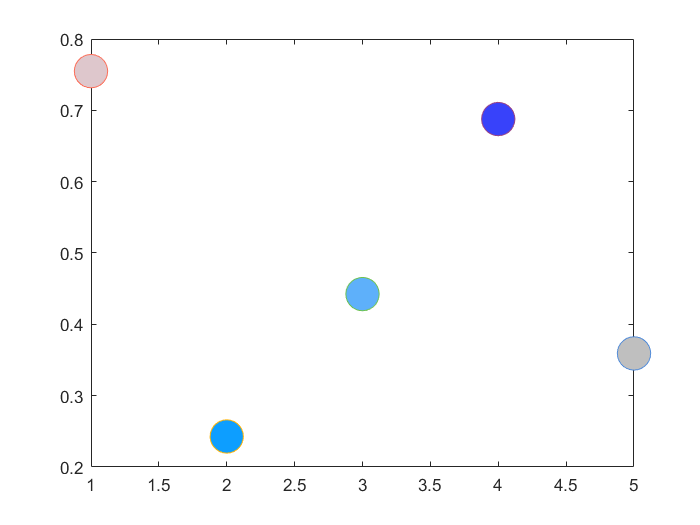

clear;clc;
% 假如有这么 5 个目标吧
x = 1:5;
y = rand(1, 5);
% 触发条件
condition = randi(5, [30, 1]);
% 先画一个随机的图表示 5 个目标
[all_themes, all_colors] = GetColors(); 
objs = [];
for i = 1:5
    h = plot(x(i), y(i), 'o', 'MarkerSize', 20, 'Color', all_colors(i, :), 'MarkerFaceColor', all_colors(i, :));
    objs = [objs, h];
    hold on
end
hold off
% 模拟 30 个过程 根据条件改变点的颜色
for i = 1:30
    objs(condition(i)).MarkerFaceColor = all_colors(5 * i, :);
    pause(0.2);
end